cd("C:\Users\rusco\OneDrive - University of Warwick\Admin\Archives\Documents\GitHub\LatticeWorks\TopOpt")
% This work is based on DEMO 13/14

% load('sample.mat')

 
% % Create a PDE model
% model = createpde("structural","static-solid");
% 
% % Import geometry from a STEP file
% importGeometry(model, 'Planet-18-Teeth-1.8mm-Mod.step');
% 
% material_yield_strength = 50e6; % MPa
% material_E = 2100e6; % Pa, 2.1 GPa
% material_v = 0.33;
% 
% % Visualize the imported geometry
% figure;
% pdegplot(model, 'FaceLabels', 'on', 'FaceAlpha', 0.5);
% title('Imported Gear Geometry');
% 
% teeth_faces = [14,24,31,38,48,55,62,72,79,86,96,103,110,120,127,134,144,151];
% 
% teeth_force = 100; % N
% area_mm2 = 66.441 * 1e-6;
% pressure = teeth_force / area_mm2;
% % Apply pressure load to each gear tooth face
% structuralBoundaryLoad(model,"Face",teeth_faces,"Pressure",pressure);
% 
% structuralProperties(model,"YoungsModulus",material_E,"PoissonsRatio",material_v);
% structuralBC(model,"Face",8,"Constraint","fixed");
% % generateMesh(model, 'GeometricOrder', 'quadratic','Hmax',0.0005);
% % fprintf('%g k Elements created',size(model.Mesh.Elements,2)./1000);
% 
% figure
% pdeplot3D(model)
% title("Mesh with Quadratic Tetrahedral Elements");
% 
% % result = solve(model);
% 
% maxVonMises = max(result.VonMisesStress); % As the load is distributed using surface traction and surface traction = F / A
% fprintf("Max Von Mises is %g MPa.", (maxVonMises / 1e6) );
% fprintf("Safety Factor is %.2f.", (material_yield_strength / (maxVonMises)));

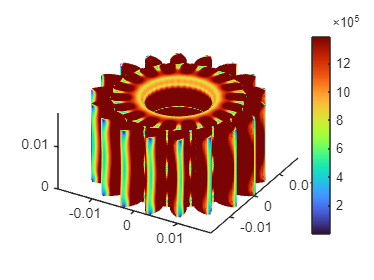

% Data to visualize
meshData = result.Mesh;
nodalData = result.VonMisesStress;
deformationData = result.Displacement;

% Create PDE result visualization
resultViz3 = pdeviz(meshData,nodalData, ...
    "DeformationData",deformationData, ...
    "DeformationScaleFactor",0, ...
    "ColorLimits",[1700 1386000]);


% Clear temporary variables
clearvars meshData nodalData deformationData

% Assuming a 2D problem
x = result.Mesh.Nodes(1, :); % x-coordinates
y = result.Mesh.Nodes(2, :); % y-coordinates
vonMisesStress = result.VonMisesStress;

% Define grid limits based on your data
xq = linspace(min(x), max(x), 100); % 100 points in x-direction
yq = linspace(min(y), max(y), 100); % 100 points in y-direction
[Xq, Yq] = meshgrid(xq, yq);

% Create the interpolant function
F = scatteredInterpolant(x', y', vonMisesStress, 'linear', 'none');

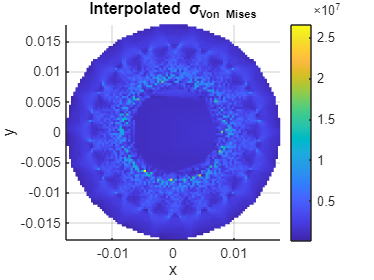


% Evaluate the interpolant at the grid points
stress_xy_grid = F(Xq, Yq);

% Plot the interpolated stress field
figure;
surf(Xq, Yq, stress_xy_grid, 'EdgeColor', 'none');
colorbar;
title('Interpolated \sigma_{Von Mises}');
xlabel('x');
ylabel('y');

view(2); % top down view
axis tight;
grid on;

% 3D Interpolation
x = result.Mesh.Nodes(1, :); % x-coordinates
y = result.Mesh.Nodes(2, :); % y-coordinates
z = result.Mesh.Nodes(3, :); % z-coordinates
vonMisesStress = result.VonMisesStress;

% Define grid limits based on your data
xq = linspace(min(x), max(x), 100); % 100 points in x-direction
yq = linspace(min(y), max(y), 100); % 100 points in y-direction
zq = linspace(min(z), max(z), 100); % 100 points in z-direction

% Create meshgrid for 3D interpolation
[Xq, Yq, Zq] = meshgrid(xq, yq, zq);

% Create the interpolant function
F = scatteredInterpolant(x', y', z', vonMisesStress, 'linear', 'none');

% Evaluate the interpolant at the grid points
stressGrid = F(Xq, Yq, Zq);

% masking
alphaVal = 0.001;
shp = alphaShape(x', y', z', alphaVal);
insideMask = inShape(shp, Xq, Yq, Zq);
stressGrid(~insideMask) = NaN;

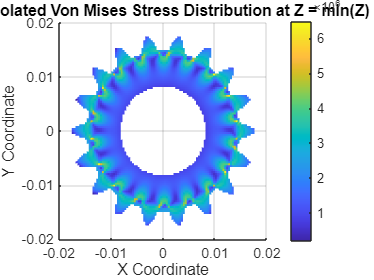

% Plot the interpolated von Mises stress distribution
figure;
surf(Xq(:,:,1), Yq(:,:,1), stressGrid(:,:,1), 'EdgeColor', 'none');
colorbar;
title('Interpolated Von Mises Stress Distribution at Z = min(Z)');
xlabel('X Coordinate');
ylabel('Y Coordinate');
zlabel('Von Mises Stress');
view(2);

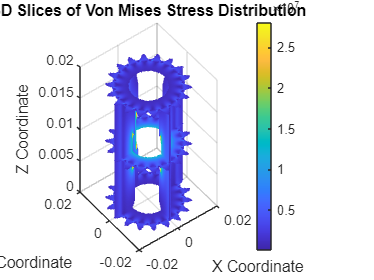

% Assuming 'stressGrid' is your 3D stress data
% and 'Xq', 'Yq', 'Zq' are your 3D grid coordinates

% Define slice positions along each axis
xslice = [min(Xq(:)), mean(Xq(:)), max(Xq(:))]; % Slices along x-axis
yslice = [min(Yq(:)), mean(Yq(:)), max(Yq(:))]; % Slices along y-axis
zslice = [min(Zq(:)), mean(Zq(:)), max(Zq(:))]; % Slices along z-axis

% Create the slice plot
figure;
slice(Xq, Yq, Zq, stressGrid, xslice, yslice, zslice);
shading interp;
colorbar;
title('3D Slices of Von Mises Stress Distribution');
xlabel('X Coordinate');
ylabel('Y Coordinate');
zlabel('Z Coordinate');

% % Find the min and max stress, ignoring NaN
% minStress = min(stressGrid(:), [], 'omitnan');
% maxStress = max(stressGrid(:), [], 'omitnan');
% 
% % Preallocate infillGrid
% infillGrid = nan(size(stressGrid));
% 
% % Loop or vectorized approach: map stress to [0..1]
% infillGrid = (stressGrid - minStress) ./ (maxStress - minStress);

% Calculate the 95th percentile stress value
p95Stress = prctile(stressGrid(:), 99);

% Clamp stress values above the 95th percentile
clampedStress = min(stressGrid, p95Stress);

% Compute the minimum stress (ignoring NaNs)
minStress = min(clampedStress(:), [], 'omitnan');

% Normalize using the clamped maximum value
infillGrid = (clampedStress - minStress) ./ (p95Stress - minStress);

% Clamp to [0, 1]
infillGrid(infillGrid < 0) = 0;
infillGrid(infillGrid > 1) = 1;

% Now clamp to [0.2..0.8]
%   0   -> 0%  infill
%   1   -> 100% infill
% but we only let it go from 0.2 to 0.8
infillGrid = 0.2 + 0.6 * infillGrid;

% For any NaN stress, set infill to 0
infillGrid(isnan(stressGrid)) = NaN;

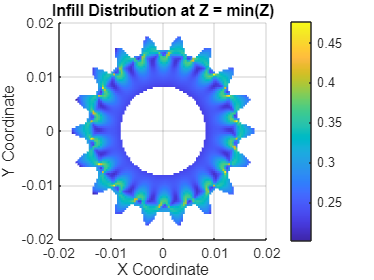

% Infill Distribution
figure;
surf(Xq(:,:,1), Yq(:,:,1), infillGrid(:,:,1), 'EdgeColor', 'none');
colorbar;
title('Infill Distribution at Z = min(Z)');
xlabel('X Coordinate');
ylabel('Y Coordinate');
zlabel('Von Mises Stress');
view(2);

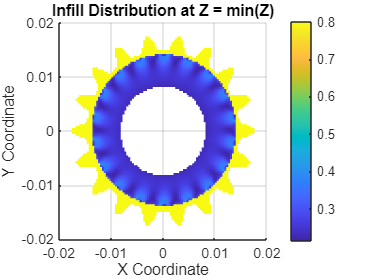

% Gear tooth radius
radius = 0.01395;

% Logical mask of points outside circle
circleMask = (Xq.^2 + Yq.^2) <= radius^2;
infillGrid(~circleMask & ~isnan(infillGrid)) = 0.8;

% Infill Distribution with teeth 100%
figure;
surf(Xq(:,:,1), Yq(:,:,1), infillGrid(:,:,1), 'EdgeColor', 'none');
colorbar;
title('Infill Distribution at Z = min(Z)');
xlabel('X Coordinate');
ylabel('Y Coordinate');
zlabel('Von Mises Stress');
view(2);

## Access model elements and patch data

rho = infillGrid;
v = 1; % im2patch voxel?

% Patch rho information to Elements and Faces
[E,V]=im2patch(infillGrid,true(size(infillGrid)),'h',v);
[F,rho_F] = element2patch(E,infillGrid(:));

% Boundary faces
indBoundaryFaces = tesBoundary(F);
Fb = F(indBoundaryFaces,:);

% define face boundary rho values
if size(Fb,2)==4
    Fb = [Fb(:,[1 2 3]); Fb(:,[3 4 1]);]; % force to be triangles to be compatible with tet volume based in/out testing
    rho_Fb = [rho_F(indBoundaryFaces); rho_F(indBoundaryFaces)];
else
    rho_Fb = rho_F(indBoundaryFaces);
end

## Mapping the density field to the equivalent gyroid levelSet field

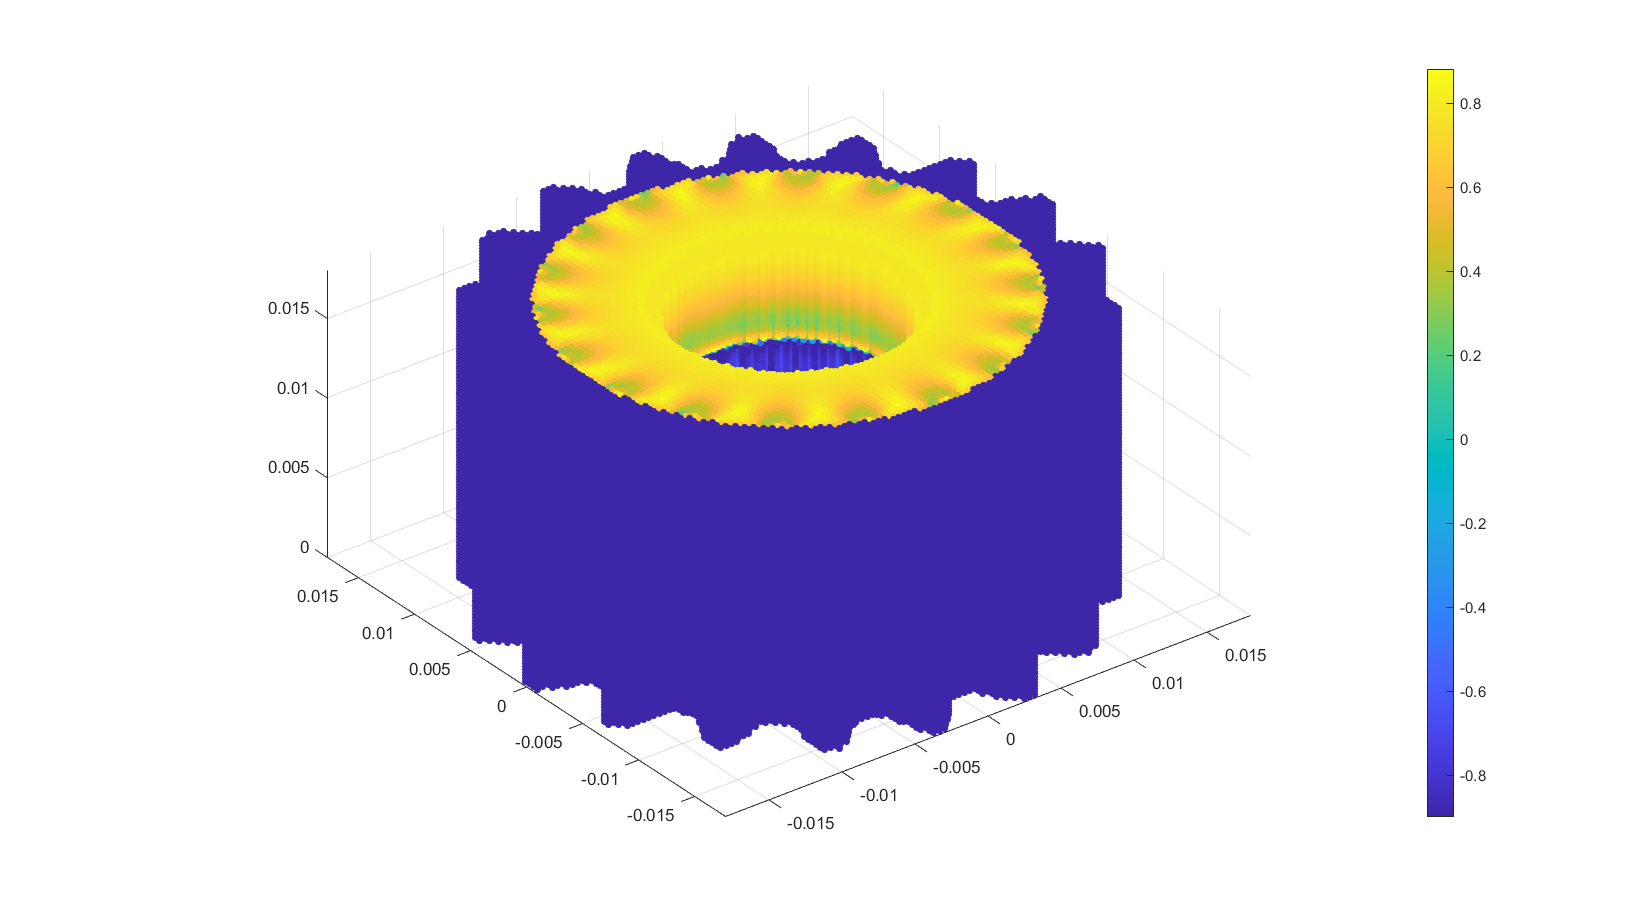

rho_VG = infillGrid;

l=(rho_VG-0.5)/-(1/3); 
k = (2*pi)*1000; % number of periods

cFigure;  
scatter3(Xq(:),Yq(:),Zq(:),20,l(:),'filled');
axis tight; axis equal; 
colorbar;

## Evaluate triply periodic function

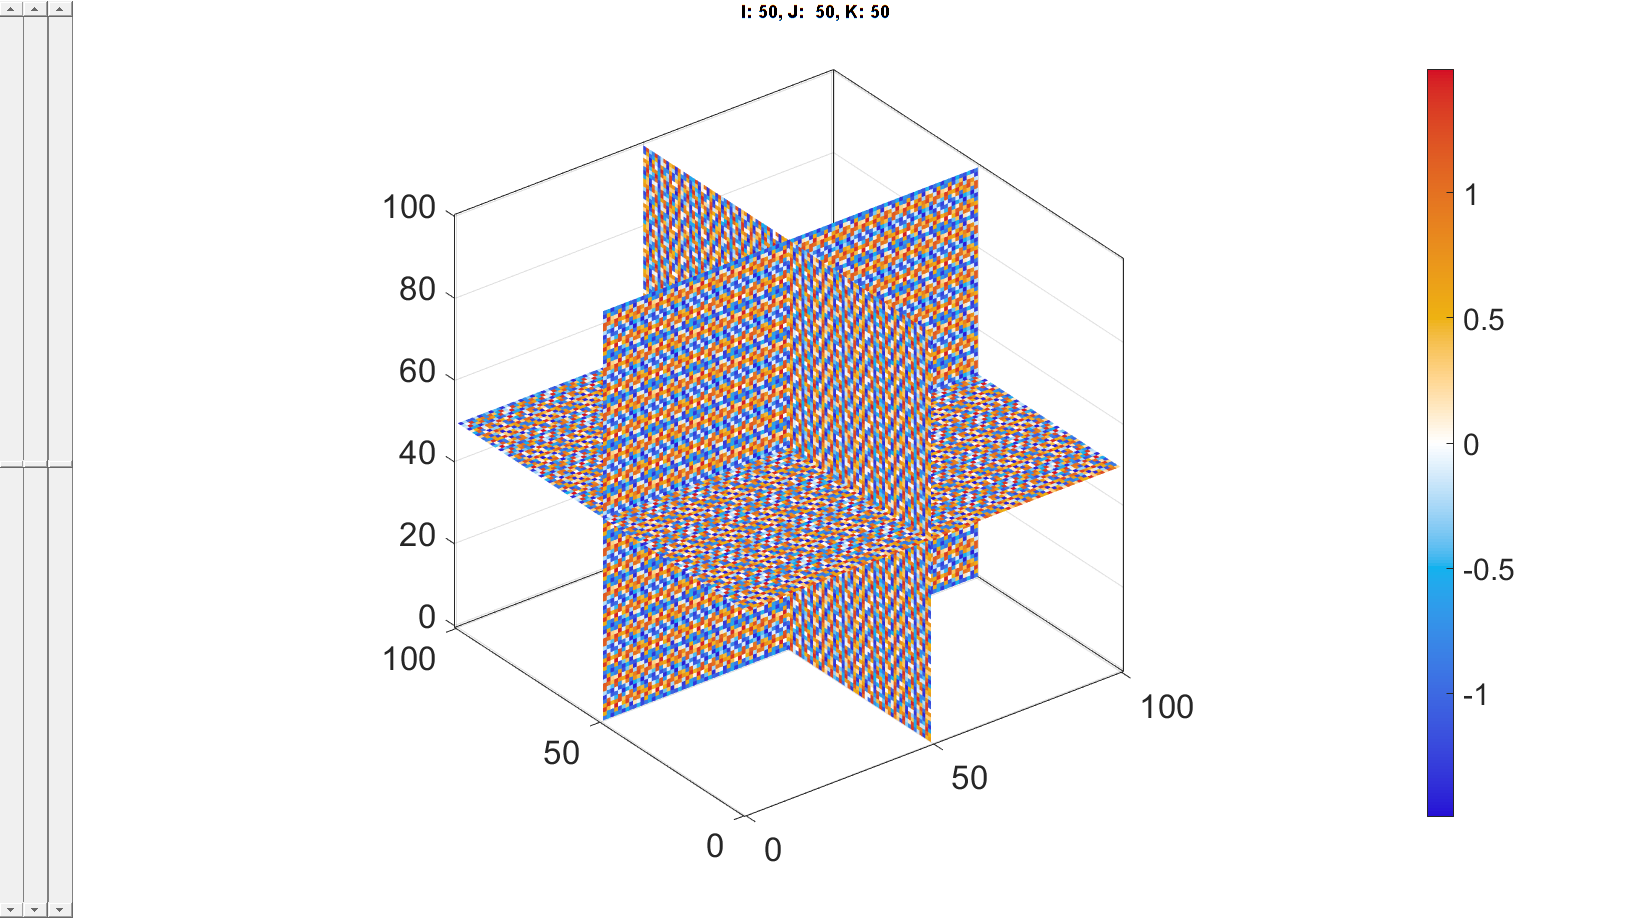

S=(sin(k.*Xq).*cos(k.*Yq))+(sin(k.*Yq).*cos(k.*Zq))+(cos(k.*Xq).*sin(k.*Zq)); 
sv3(S); colormap warmcold;


% axis([-0.02 0.02 -0.02 0.02 0 0.02]);

% xlim([-0.02 0.02])
% ylim([-0.02 0.02])

## Mapping the density field to the equivalent gyroid levelSet field

Gyroid "spans" -1.5-1.5, shift so minimum is at 1

i=2.5; % Leads to a minimum of 1 later
Sg=S+i; % S=-S-i;
l=l+i; % l=-l-i; % i:i+s
Sg=Sg./l; 

Arrays have incompatible sizes for this operation.

Related documentation


Sg=Sg-1; % bringing back to zero levelset
Sg=-Sg; % Negative

sv3(S); colormap warmcold;
sv3(Sg); colormap warmcold;

[Fg,Vg] = isosurface(Xq,Yq,Zq,Sg,0);
[Fgc,Vgc] = isocaps(Xq,Yq,Zq,Sg,0);

## Joining the two surfaces

[Fsn,Vsn,Csn]=joinElementSets({Fg,Fgc},{Vg,Vgc});
[Fsn,Vsn]=patchCleanUnused(Fsn,Vsn); % Remove unused nodes
[Fsn,Vsn]=mergeVertices(Fsn,Vsn); % Merge nodes

## Visualize surface

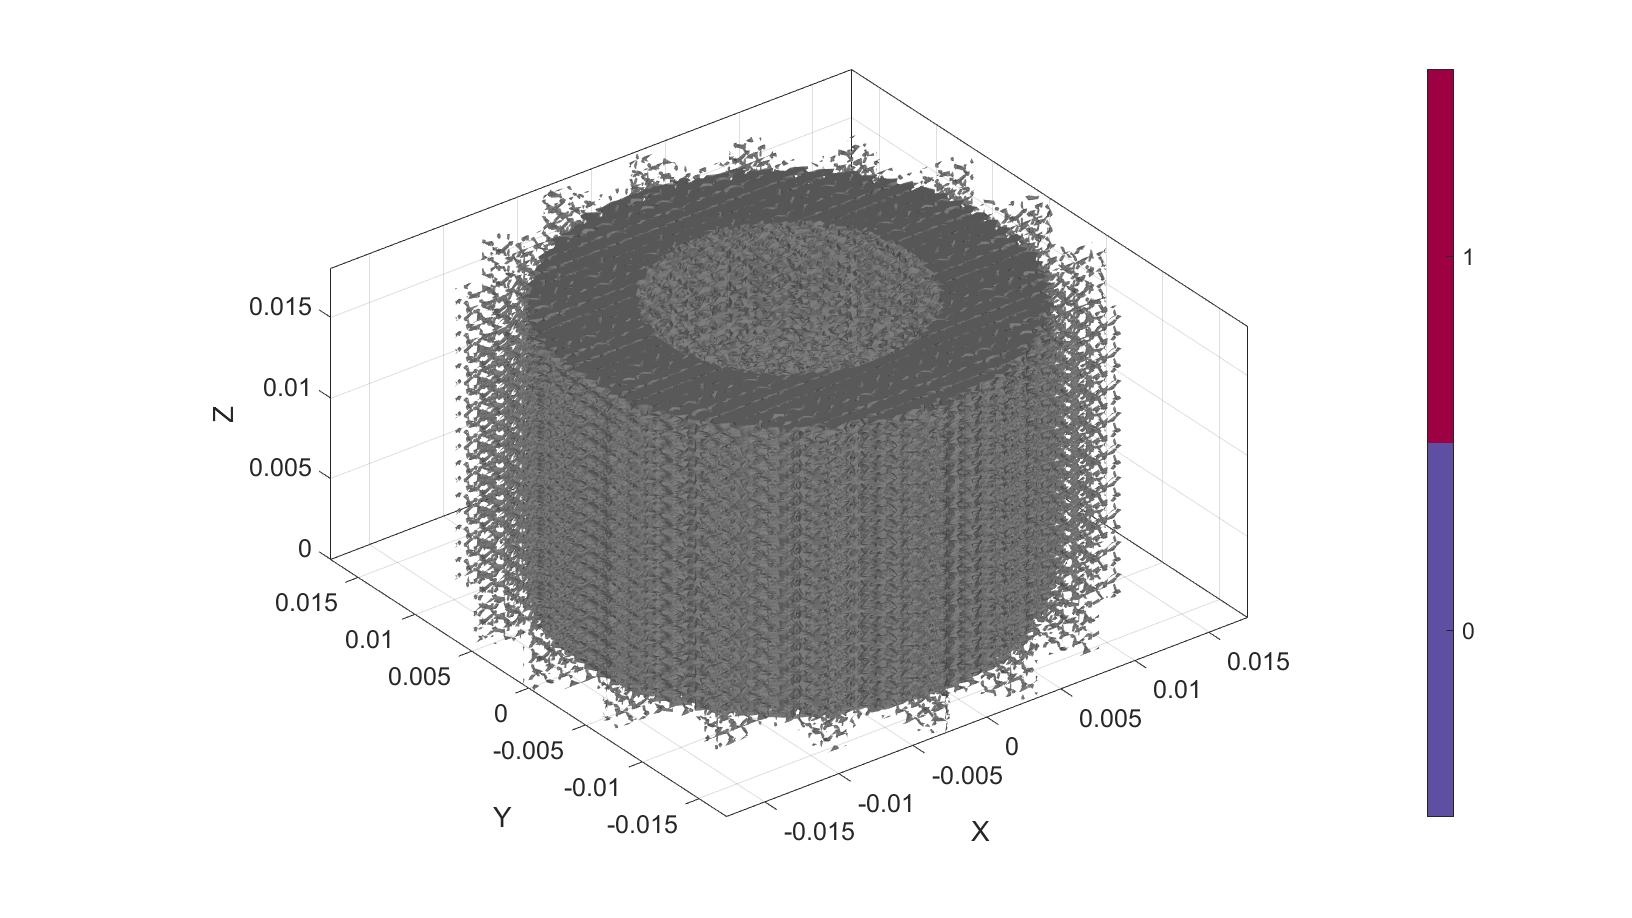

cFigure; 
gpatch(Fsn,Vsn,'kw','none',1);
axisGeom; colormap spectral; icolorbar; 
camlight headlight; axis on;

drawnow;